# **K.5 Ausbreitungsmodell einer Infektionskrankheit**

## Interpretation der Parameter in der Differentialgleichung:

    Bei der Literaturrecherche stellt man schnell fest, dass das in der Aufgabenstellung angegebene Modell dem SI-Modell (Susceptible-Infective Model) im Gebiet der Epidemiologie entspricht. Nach dem Gegenüberstellen der Differentialgleichungen in den zwei Modellen ergibt sich bezüglich der Parameter folgendes:

k = sqrt(r * c * N), 

mit r als [Replikationsrate](https://de.wikipedia.org/wiki/Replikationsrate), c als Wechselwirkungsterm und N als die Gesamtbevölkerung.

## 1. Simulationsergebnis mit den angegebenen Parametergrößen

    Zunächst laufen wir die Simulation anhand den angegebenen Größen für y0 und k. Das Modell nennt sich "Ausbreitungsmodell.slx".	   

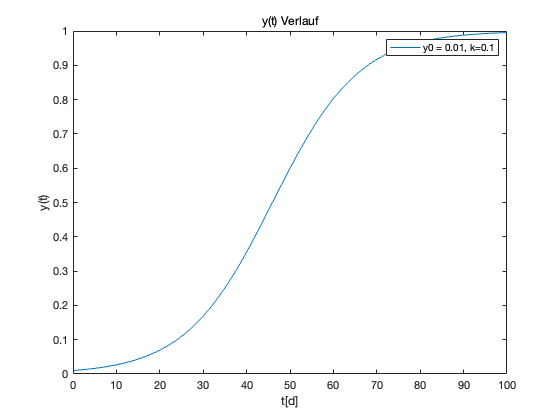

clc
close 
clear
%% load model
model = 'Ausbreitungsmodell';
load_system(model)

%% set parameters
in = Simulink.SimulationInput(model);
in = in.setVariable('y0', 0.01, 'Workspace', 'Ausbreitungsmodell');
in = in.setVariable('k', 0.1, 'Workspace', 'Ausbreitungsmodell');
out = sim(in);

%% plot figures
% y(t)
figure
plot(out.logsout{2}.Values)
legendText = ['y0 = 0.01, k=0.1'];
legend(legendText);
xlabel('t[d]')
ylabel('y(t)')
title('y(t) Verlauf')
saveas(gcf,fullfile('images', 'yt_Verlauf'), 'jpeg')

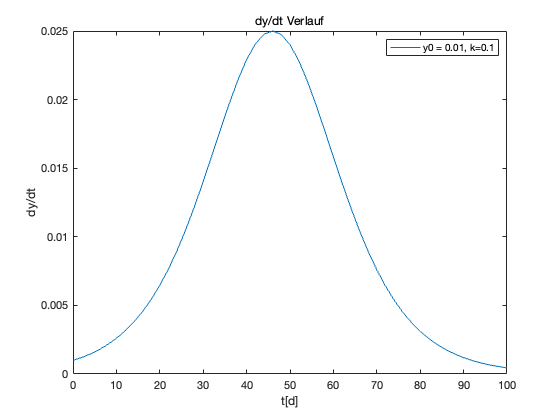


% dy/dt
figure
plot(out.logsout{1}.Values)
legendText = ['y0 = 0.01, k=0.1'];
legend(legendText);
xlabel('t[d]')
ylabel('dy/dt')
title('dy/dt Verlauf')
saveas(gcf,fullfile('images', 'dydt_Verlauf'), 'jpeg')

    In den Diagrammen ist deutlich erkennbar, dass der Anteil der Infizierten einen zeitlich typischen S-Form darstellt. Die Geschwindigkeit der Ausbreitung nimmt zunächst zu, bis der Wendepunkt erreicht wird, und danach nimmt wieder ab, bis die ganze Bevölkerung angesteckt wird. 

## 2. Bitte verändern Sie die Parameterwerte des Problems, so dass sich interessante Zustände (stabiles/instabiles Systemverhalten) ergeben. Beschreiben Sie kurz, ob eine solche Parameterkombination möglich ist. 

### 2.1 Veränderung y0

    In der Praxis ist eine Pandemieausbreitung relativ früh erkennbar, sodass sich der y0 Wert bei der Parametervariation ausgehend von 0,1 in den niedrigen Bereich ausstrecken soll.

y0 = logspace(-5,-1, 5);

for p = 1:1:length(y0)
    in_y0(p) = Simulink.SimulationInput(model);
    in_y0(p) = in_y0(p).setVariable('y0', y0(p), 'Workspace', 'Ausbreitungsmodell');
    in_y0(p) = in_y0(p).setVariable('k', 0.1, 'Workspace', 'Ausbreitungsmodell');
end

out = parsim(in_y0, 'ShowProgress', 'on');

[21-Feb-2021 15:30:09] Checking for availability of parallel pool...
[21-Feb-2021 15:30:09] Running simulations...
[21-Feb-2021 15:30:10] Completed 1 of 5 simulation runs
[21-Feb-2021 15:30:10] Completed 2 of 5 simulation runs
[21-Feb-2021 15:30:11] Completed 3 of 5 simulation runs
[21-Feb-2021 15:30:11] Completed 4 of 5 simulation runs
[21-Feb-2021 15:30:11] Completed 5 of 5 simulation runs


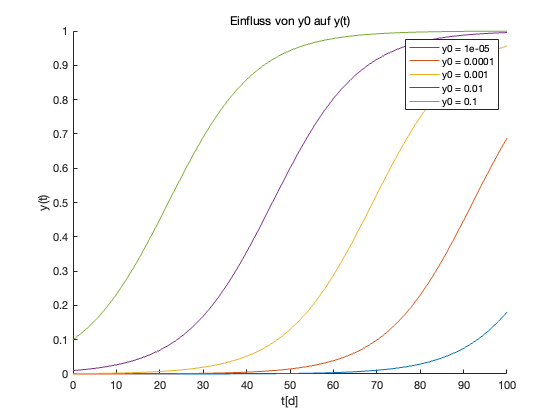


% y(t) under y0 variation
figure 
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_y0)
xlabel('t[d]')
ylabel('y(t)')
title('Einfluss von y0 auf y(t)')
saveas(gcf,fullfile('images', 'yt_y0'), 'jpeg')

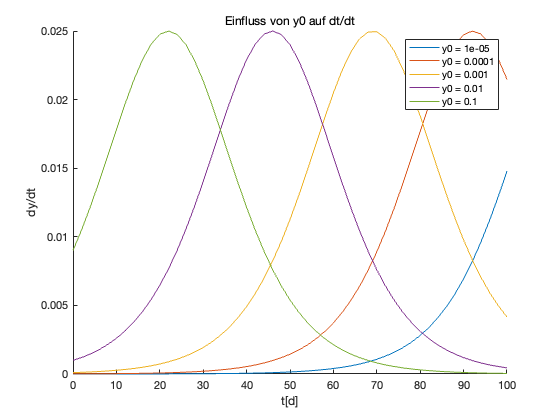


% dy/dt under y0 variation
figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)
    legendText_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_y0)
xlabel('t[d]')
ylabel('dy/dt')
title('Einfluss von y0 auf dt/dt')
saveas(gcf,fullfile('images', 'dydt_y0'), 'jpeg')

    In der ersten Grafik ist leicht zu entnehmen, dass sich die S-Kurve mit einem größeren y0 nach oben links verschiebt, sodass die Ausbreitungsgeschwindigkeit früher steigt und am Ende des Ablaufs früher stagniert.

###  2.2 Veränderung k

    Ausgehend von dem gegebenen Wert k = 0.1 wird eine Streuung k = 0.025 bis k = 0.2 in die Simulation eingesetzt. Ein zu hoher k-Wert ist aus epidemiolgischer Sicht nicht als sinnvoll anzusehen.

k = 0.025:0.025:0.2;

for p = 1:1:length(k)
    in_k(p) = Simulink.SimulationInput(model);
    in_k(p) = in_k(p).setVariable('k', k(p), 'Workspace', 'Ausbreitungsmodell');
    in_k(p) = in_k(p).setVariable('y0', 0.01, 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_k, 'ShowProgress', 'on');

[21-Feb-2021 15:30:15] Checking for availability of parallel pool...
[21-Feb-2021 15:30:15] Running simulations...
[21-Feb-2021 15:30:15] Completed 1 of 8 simulation runs
[21-Feb-2021 15:30:16] Completed 2 of 8 simulation runs
[21-Feb-2021 15:30:16] Completed 3 of 8 simulation runs
[21-Feb-2021 15:30:16] Completed 4 of 8 simulation runs
[21-Feb-2021 15:30:16] Completed 5 of 8 simulation runs
[21-Feb-2021 15:30:16] Completed 6 of 8 simulation runs
[21-Feb-2021 15:30:16] Completed 7 of 8 simulation runs
[21-Feb-2021 15:30:16] Completed 8 of 8 simulation runs


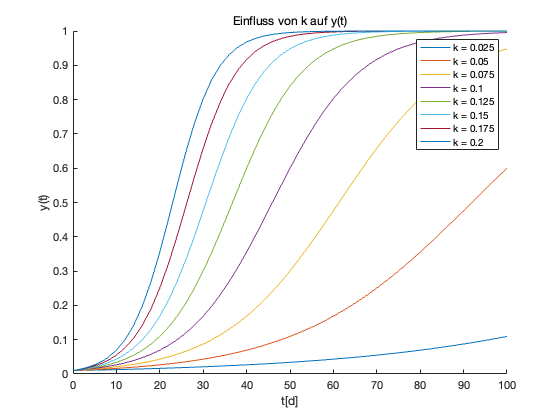


% y(t) under k variation
figure 
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_k{p} = ['k = ', num2str(k(p))];
end
legend(legendText_k)
xlabel('t[d]')
ylabel('y(t)')
title('Einfluss von k auf y(t)')
saveas(gcf,fullfile('images', 'yt_k'), 'jpeg')

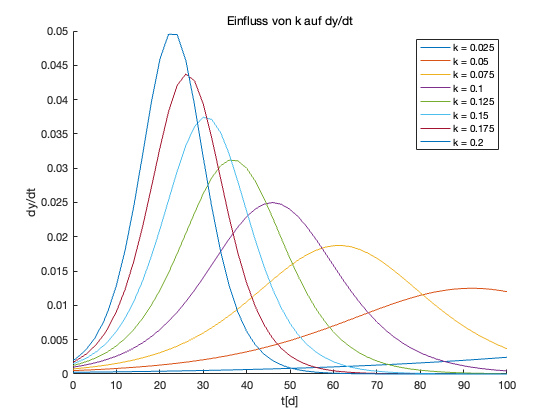


% dy/dt under k variation
figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)
    legendText_k{p} = ['k = ', num2str(k(p))];
end
legend(legendText_k)
xlabel('t[d]')
ylabel('dy/dt')
title('Einfluss von k auf dy/dt')
saveas(gcf,fullfile('images', 'dydt_k'), 'jpeg')

    Aus dem dy/dt Diagramm kann man die Schlussfolgerung ziehen, dass der k-Wert eine Schlüsselrolle zur Eindämmung des Ausbruchs einnimmt, da dy/dt von der Größe k maßgeblich beeinflusst wird. Insbesondere bei kleinen k-Werten führt eine kleinere k-Größe zu einem deutlich flacheren dy/dt Verlauf.

## 3 Rrki berechnen

    Es ist wünschenswert, die Pandemieausbreitung anhand einem gängigeren Index zu betrachten, da k noch rechnerisch unbekannten Weckselwirkungswert in sich hat. Wir verwenden den Rrki Index, der auch in zahlreichen populärwissentschaftlichen Medien vorzufinden ist. Rrki ist auch eine zeitabhängige Größe, die folgendermaßen aufgeschlüsselt werden kann, und zwar:

 mit s = 4 und t ≥ 2s.

    Der Rrki-Verlauf bietet einen anderen Sichtwinkel zur Analyse des Ausbruchs. Wir folgen ebenfalls dem Ansatz wie bisher, nämlich y0 und k zu variieren. Die Berechnung erfolgt im Subsystem "Rrki berechnen" des Simulink-Modells.

### 3.1 Veränderung y0

%% Rrki analysis based on y0 Variation
y0 = 0.0025:0.0025:0.01;
y0(5)=0.05;
y0(6)=0.1;

for p = 1:1:length(y0)
    in_Rrki_y0(p) = Simulink.SimulationInput(model);
    in_Rrki_y0(p) = in_Rrki_y0(p).setVariable('k', 0.1, 'Workspace', 'Ausbreitungsmodell');
    in_Rrki_y0(p) = in_Rrki_y0(p).setVariable('y0', y0(p), 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_Rrki_y0, 'ShowProgress', 'on');

[21-Feb-2021 15:30:20] Checking for availability of parallel pool...
[21-Feb-2021 15:30:20] Running simulations...
[21-Feb-2021 15:30:20] Completed 1 of 6 simulation runs
[21-Feb-2021 15:30:20] Completed 2 of 6 simulation runs
[21-Feb-2021 15:30:20] Completed 3 of 6 simulation runs
[21-Feb-2021 15:30:21] Completed 4 of 6 simulation runs
[21-Feb-2021 15:30:21] Completed 5 of 6 simulation runs
[21-Feb-2021 15:30:21] Completed 6 of 6 simulation runs


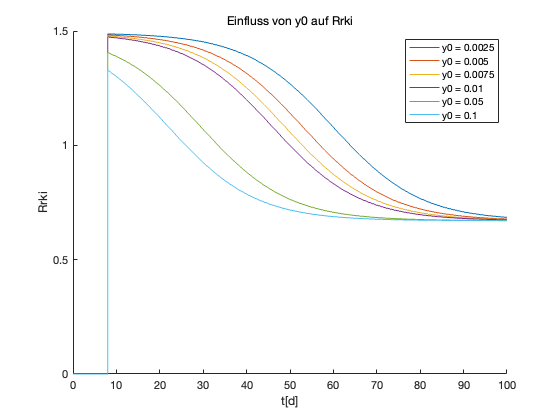


figure 
hold on

for p=1:1:length(out)
    plot(out(p).logsout{3}.Values)
    legendText_Rrki_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_Rrki_y0)
xlabel('t[d]')
ylabel('Rrki')
title('Einfluss von y0 auf Rrki')
saveas(gcf,fullfile('images', 'Rrki_y0'), 'jpeg')

    Daraus ist erkennbar, dass Rrki trotz des veränderlichen y0-Wertes am denselben Niveau stagniert. Auch wichtig ist, dass Rrki die Entwicklung der Pandemie nur ansatzweise wiederspiegelt. Der Grund hierfür ist, dass die in der Streuung größere y0 Werte ungewohnt kleinere Spitzen verursachen. Eine mögliche Begründung beruht auf der Interpretation des Rrki Wertes, dass Rrki die Anzahl weiterer Infektionen durch einen vorliegenden Infizierten repräsentiert. Ist ein hoher Anteil der Bevölkerung bereits angesteckt, kann lediglich eine beschränkte Anzahl an Menschen infiziert werden. Wichtig ist außerdem u.a. die absolute Zahl der täglichen Neuinfektionen.

### 3.2 Veränderung k

%% Rrki analysis based on k Variation
k = 0.025:0.025:0.2;

for p = 1:1:length(k)
    in_Rrki_k(p) = Simulink.SimulationInput(model);
    in_Rrki_k(p) = in_Rrki_k(p).setVariable('y0', 0.01, 'Workspace', 'Ausbreitungsmodell');
    in_Rrki_k(p) = in_Rrki_k(p).setVariable('k', k(p), 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_Rrki_k, 'ShowProgress', 'on');

[21-Feb-2021 15:30:22] Checking for availability of parallel pool...
[21-Feb-2021 15:30:22] Running simulations...
[21-Feb-2021 15:30:23] Completed 1 of 8 simulation runs
[21-Feb-2021 15:30:23] Completed 2 of 8 simulation runs
[21-Feb-2021 15:30:23] Completed 3 of 8 simulation runs
[21-Feb-2021 15:30:23] Completed 4 of 8 simulation runs
[21-Feb-2021 15:30:23] Completed 5 of 8 simulation runs
[21-Feb-2021 15:30:23] Completed 6 of 8 simulation runs
[21-Feb-2021 15:30:23] Completed 7 of 8 simulation runs
[21-Feb-2021 15:30:24] Completed 8 of 8 simulation runs


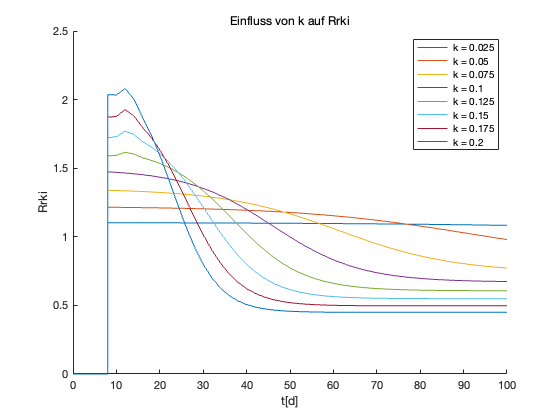


figure 
hold on

for p=1:1:length(out)
    plot(out(p).logsout{3}.Values)
    legendText_Rrki_k{p} = [' k = ', num2str(k(p))];
end
legend(legendText_Rrki_k)
xlabel('t[d]')
ylabel('Rrki')
title('Einfluss von k auf Rrki')
saveas(gcf,fullfile('images', 'Rrki_k'), 'jpeg')

    Der Einfluss des k-Werts auf die zeitliche Entwicklung wird im Diagramm aufgezeigt. Höhere k-Werte führen zum schnelleren Abstieg der Kurve, was auf die rasante Reduzierung gesunder Bevölkerung zurückzuführen ist. Bei einem sehr kleinen k-Wert bleibt der Rrki über sehr lange Zeit quasistationär leicht oberhalb eins.

## 4. Implementieren Sie verschiedene Strategien zur Eindämmung der Infektion, z.B. ein Kontaktverbot 

    Grundsätzlich bestehen zwei Möglichkeiten, die Infektionsanzahl zu reduzieren:

- durch Reduktion der Replikationsrate r (Hygienemaßnahmen, Abstand usw.) und

- durch Reduktion der Gesunden durch Immunisierung (Impfung usw.), also Reduktion von N.

    Dementsprechend muss das Simulationsmodell auch noch je nach der angewendeten Strategie vernünftig erweitert werden. Das neue Modell wird als "Eindaemmungsstrategien.slx" genannt.

    Die unten aufgeführten Strategien wurden in zwei Subsystemen implementiert. Der Auswahl der Strategien erfolgt per Subsystem "Strategie_Selector". Die Ausgangsgröße des jeweiligen Strategie_Selectors werden je nach der Strategie modifiziert, indem sie beim Einsatz der einen Strategie zum neuen Wert gesetzt wird und beim Einsatz der anderen Strategie zum ursprünglichen Wert gesetzt wird.

%% load new model
model_s = 'Eindaemmungsstrategien';
load_system(model_s)

### 4.1 Reduktion der Replikationsrate r

    Bekämpfungsstrategien, wie Lockdown, Abstandsregeln sowie sämtliche Hygienenmaßnahmen lassen sich der Reduktion der Replikationsrate r zuordnen, was wir hier durch abrupte Änderung des k-Terms zu verschiedenen Zeitpunkten im Ablauf der Ausbreitung untersuchen wollen.

    Da sich k in drei weitere Terme r, c, N aufschlüsseln lässt, ist hier lediglich eine qualitative Untersuchung möglich. Wir gehen davon aus, dass k durch die eingesetzte Strategie auf k/3 redurziert wird. Betrachtet werden 3 Zeitpunkte zum Einsatz der Strategien: vor dem Wendepunkt, auf dem Wendepunkt, nach dem Wendepunkt. Zum Vergleich stellen wir noch eine Simulation ohne Eindämmung durch tk > 100s .

tk = [23;46;69;101]; % time(s) when the strategy is deployed 

for p = 1:1:length(tk)
    in_r(p) = Simulink.SimulationInput(model_s);
    in_r(p) = in_r(p).setVariable('tk', tk(p), 'Workspace', 'Eindaemmungsstrategien');
    % select the corresponding strategy
    in_r(p) = in_r(p).setVariable('r_strategie', 1, 'Workspace', 'Eindaemmungsstrategien');
    in_r(p) = in_r(p).setVariable('I_strategie', 0, 'Workspace', 'Eindaemmungsstrategien');
end

out = parsim(in_r, 'ShowProgress', 'on');

[21-Feb-2021 15:30:25] Checking for availability of parallel pool...
[21-Feb-2021 15:30:25] Running simulations...
[21-Feb-2021 15:30:34] Completed 1 of 4 simulation runs
[21-Feb-2021 15:30:35] Completed 2 of 4 simulation runs
[21-Feb-2021 15:30:35] Completed 3 of 4 simulation runs
[21-Feb-2021 15:30:36] Completed 4 of 4 simulation runs


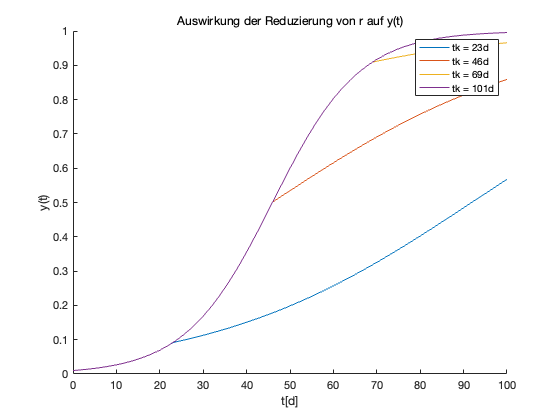


% plot y(t)
figure 
hold on

for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)
    legendText_tk{p} = ['tk = ', num2str(tk(p)), 'd'];
end
legend(legendText_tk)
xlabel('t[d]')
ylabel('y(t)')
title('Auswirkung der Reduzierung von r auf y(t)')
saveas(gcf,fullfile('images', 'yt_r'), 'jpeg')

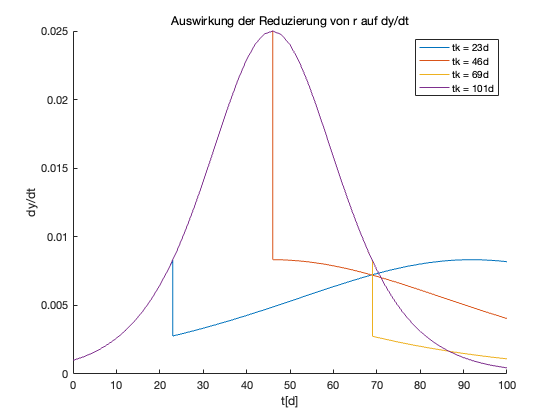


% plot dy/dt
figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_tk{p} = ['tk = ', num2str(tk(p)), 'd'];
end
legend(legendText_tk)
xlabel('t[d]')
ylabel('dy/dt')
title('Auswirkung der Reduzierung von r auf dy/dt')
saveas(gcf,fullfile('images', 'dydt_r'), 'jpeg')

    Daraus lässt sich schließen, dass die positive Auswirkung der korrespondierten Maßnahmen zur Reduzierung der Replikationsrate r desto größer ist, je früher man sie in Gang setzt. Hygienenmaßnahmen spät im S-Verlauf bzw. nach dem Wendepunkt kann die weitere Ausbreitung des Viren nur sanft eindämmen. 

### 4.2 Immunisierung

    Da die Auswirkung von Immunisierung nur schwer in dem einfachen SI-Modell analysiert werden kann, können wir die angegebene Gleichung mit einem zusätzlichen Term i erweitern. Der Term i bezeichnet den geimpften Bevölkerungsanteil pro Zeiteinheit (hier Tag). Hierzu wird angenommen, dass die Immunisierung zum Simulationsanfang sofort beginnt. Der Fokus der Analyse hier liegt auf der Impfungsgeschwindigkeit, was durch die Variation von i dargestellt werden kann. Zur Information lautet die Größe von i nach dem aktuellen Impfungszustand in Deutschland nach Abrundung 1.9%.

i = 0.001:0.002:0.009; % Vaccination rate per time unit in relation to the population

for p = 1:1:length(i)
    in_I(p) = Simulink.SimulationInput(model_s);
    in_I(p) = in_I(p).setVariable('i', i(p), 'Workspace', 'Eindaemmungsstrategien'); 
    % select the corresponding strategy 
    in_I(p) = in_I(p).setVariable('r_strategie', 0, 'Workspace', 'Eindaemmungsstrategien');
    in_I(p) = in_I(p).setVariable('I_strategie', 1, 'Workspace', 'Eindaemmungsstrategien');  
end

out = parsim(in_I, 'ShowProgress', 'on');

[21-Feb-2021 15:30:39] Checking for availability of parallel pool...
[21-Feb-2021 15:30:39] Running simulations...
[21-Feb-2021 15:30:39] Completed 1 of 5 simulation runs
[21-Feb-2021 15:30:40] Completed 2 of 5 simulation runs
[21-Feb-2021 15:30:40] Completed 3 of 5 simulation runs
[21-Feb-2021 15:30:40] Completed 4 of 5 simulation runs
[21-Feb-2021 15:30:41] Completed 5 of 5 simulation runs


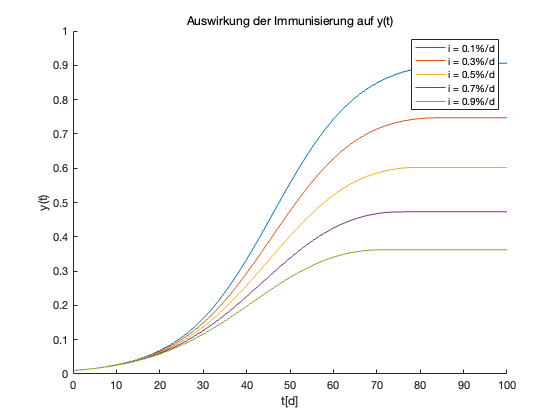


% plot y(t)
figure 
hold on

for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)
    legendText_I{p} = ['i = ', num2str(i(p)*100), '%/d'];
end
legend(legendText_I)
xlabel('t[d]')
ylabel('y(t)')
title('Auswirkung der Immunisierung auf y(t)')
saveas(gcf,fullfile('images', 'yt_I'), 'jpeg')

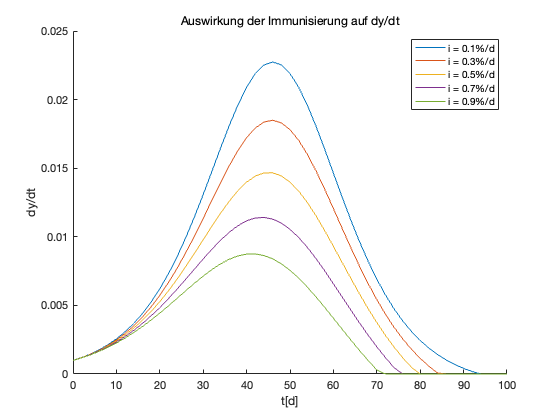


% plot dy/dt
figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_I{p} = ['i = ', num2str(i(p)*100), '%/d'];
end
legend(legendText_I)
xlabel('t[d]')
ylabel('dy/dt')
title('Auswirkung der Immunisierung auf dy/dt')
saveas(gcf,fullfile('images', 'dydt_I'), 'jpeg')

    Deutlich zu sehen ist die Auswirkung der Immunisierung. Je schneller die Bevölkerung geimpft wird, desto größer ist der Anteil geschützter bzw. gesunder Menschen am Ende der Pandemie; weiterhin ist die Ausbreitungsgeschwindigkeit langsamer.

## 5. Übertragen das Modell auf Covid-19

    Die angegebene Bedingung y(0)=0.01 bedeutet in der realen Welt einen ziemlich hohen Anteil der Infizierten, was durch verschiedenste Bemühungen zur Eindämmung erst sehr spät vorgekommen ist. Mit einer Bevölkerung in der Städteregion Aachen von c.a. 550k haben wir deswegen die Anfangsbedingung auf die realen Daten angepasst. Das heißt:

y(0) = 10/550000 =  2*10^-5

    Der Ansatz hier ist es, den k-Wert anhand der realistischen Verbreitung einzuschätzen und ins Modell einzusetzen, um die simulierte und reale Verläufe gegenüberzustellen. Daraus haben wir den k-Wert auf 0.15 eingestellt. Verwendet wurde das ursprüngliche Modell "Ausbreitungsmodell.slx".

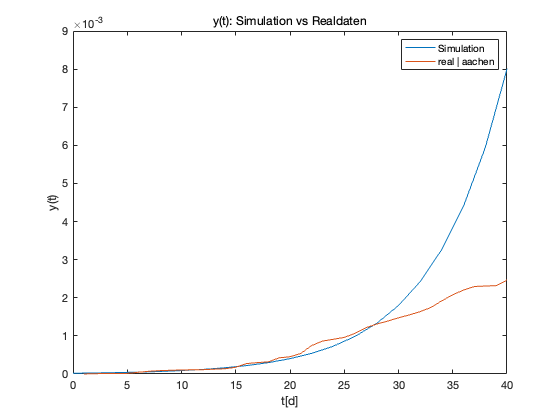

in_covid = Simulink.SimulationInput(model);
% estimated y0 and k value according to the current state in Aachen
in_covid = in_covid.setVariable('y0', 2*10^-5, 'Workspace', 'Ausbreitungsmodell');
in_covid = in_covid.setVariable('k', 0.15, 'Workspace', 'Ausbreitungsmodell');

out = sim(in_covid);

%% y(t)
% plot simulated y(t)
figure 

plot(out.logsout{2}.Values)
label1 = 'Simulation';
hold on

% read real cumulated number of corona cases in Aachen within 100 days (corresponds to simulation runtime 100s)
num = readmatrix("Fallzahl.txt");
proportion = num / 552472;

% plot real y(t)
day = 1:1:length(proportion);
plot(day,proportion)
label2 = 'real | aachen';
legend(label1, label2);
xlim([0 40]);
xlabel('t[d]')
ylabel('y(t)')
hold off
title('y(t): Simulation vs Realdaten')
saveas(gcf,fullfile('images', 'yt_sim_vs_real'), 'jpeg')

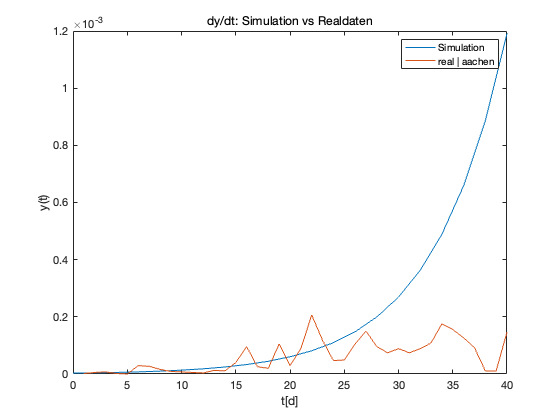


%% dy/dt
% plot simulated dy/dt
figure 

plot(out.logsout{1}.Values)
hold on

% calculate new infected based on real data
daily_new(1) = proportion(1);

for x=2:1:100
    daily_new(x) = (proportion(x)-proportion(x-1));
end

% plot real dy/dt
plot(day,daily_new)
legend(label1, label2);
xlim([0 40]);
xlabel('t[d]')
ylabel('y(t)')
hold off
title('dy/dt: Simulation vs Realdaten')
saveas(gcf,fullfile('images', 'dydt_sim_vs_real'), 'jpeg')

    In den erstellten Diagrammen ist ersichtlich, dass am Anfang der Verbreitung (Tag 0 bis Tag 30) die Simulation den realen Ablauf gut widerspiegelt. Danach (Tag 31 bis Tag 100) verliert die Simulation allerdings an Bedeutung, weil im plakativen SI-Modell keine menschliche Eingriffe zur Eindämmung der Pandemie in Bezug genommen werden. Deshalb läuft die simulierte Kurve deutlich schneller als in der realen Welt.